# Regression and Interpolation - Machine Problem 3

In this machine problem, you are going to develop your own functions for regression and interpolation. The goal is to learn how to set up matrices and to perform basic matrix operations. 

#### TASK 1. 

Import the data files "current.txt" and "normal.txt" and determine their fitting coefficients using MATLAB's built-in function from Exercise 3. Use the variables $Bc$ and $Bn$ for the fitting coefficients of the $current$ and $normal$ data sets, respectively. Solve for their corresponding fitting functions and assign them to the variables $Ic$ and $Fn$, respectively. Solve for the error between the fitting functions and the data set and assign the results to the variables $ec$ and $en$, respectively.

clear;

% Loading the data sets to the MATLAB workspace
A1 = importdata("current.txt");
tc = A1.data(:,1);
ic = A1.data(:,2);
A2 = importdata("normal.txt");
tn = A2(16:51,1);
fn = A2(16:51,2);

% Solving for the coefficients of the fitting equation
m = 4;
Bc = polyfit(tc,ic,m)

Bc = 1.0e+04 *

    4.0175   -1.0048    0.0898   -0.0034    0.0000


sumc = zeros(length(tc),1);
for i = 1:m+1
    sumc = sumc + Bc(i)*tc.^(m+1-i);
end
Ic = sumc;

Bn = polyfit(tn,fn,m)

Bn = 1.0e+03 *

   -0.0362    0.4941   -2.4005    4.8701   -3.4848


sumn = zeros(length(tn),1);
for i = 1:m+1
    sumn = sumn + Bn(i)*tn.^(m+1-i);
end
Fn = sumn;

ec = sqrt(sum((Ic-ic).^2)/(length(ic)-(m+1)))

ec = 0.0118

en = sqrt(sum((Fn-fn).^2)/(length(fn)-(m+1)))

en = 406.3524

#### TASK 2. Set-up the polynomial regression matrix

As you've seen in the video, in order to find the coefficients, $B(i)$, you will need to set up the polynomial regression matrix, as shown. Let


$$A=\left\lbrack \begin{array}{ccccc}
n & \sum_{i=1}^n x_i  & \sum_{i=1}^n x_i^2  & \cdots  & \sum_{i=1}^n x_i^m \\
\sum_{i=1}^n x_i  & \sum_{i=1}^n x_i^2  & \sum_{i=1}^n x_i^3  & \cdots  & \sum_{i=1}^n x_i^{m+1} \\
\sum_{i=1}^n x_i^2  & \sum_{i=1}^n x_i^3  & \sum_{i=1}^n x_i^4  & \cdots  & \sum_{i=1}^n x_i^{m+2} \\
\vdots  & \vdots  & \vdots  & \ddots  & \\
\sum_{i=1}^n x_i^m  & \sum_{i=1}^n x_i^{m+1}  & \sum_{i=1}^n x_i^{m+2}  &  & \sum_{i=1}^n x_i^{2m} 
\end{array}\right\rbrack$$


where $n$ is the number of data points and $m$ is the highest order of the polynomial as shown 

$\textrm{yfit}=B\left(1\right)t^m +B\left(2\right)t^{m-1} +B\left(3\right)t^{m-2} +\ldotp \ldotp \ldotp +B\left(m+1\right)$.

We define the column matrix 


$$B=\left\lbrack \begin{array}{c}
B\left(1\right)\\
B\left(2\right)\\
B\left(3\right)\\
\vdots \\
B\left(m+1\right)
\end{array}\right\rbrack$$


to be the coefficients of the polynomial fit equation, $yfit$. Finally, we define the column matrix 


$$C=\left\lbrack \begin{array}{c}
\sum_{i=1}^n y_i \\
\sum_{i=1}^n x_i y_i \\
\sum_{i=1}^n x_i^2 y_i \\
\vdots \\
\sum_{i=1}^n x_i^m y_i 
\end{array}\right\rbrack$$


such that the product of the matrices $A$ and $B$ is equal to matrix $C$, i.e.

$A\;B=C$.

This derivation has been shown in the video lecture. To get  the coefficients, you should solve for

$B=A^{-1} C$.

The first thing you need to do is set up the matrix $A$. Remember that the matrix $A$ has elements


$$A=\left\lbrack \begin{array}{ccccc}
A\left(1,1\right) & A\left(1,2\right) & A\left(1,3\right) & \cdots  & A\left(1,m+1\right)\\
A\left(2,1\right) & A\left(2,2\right) & A\left(2,3\right) & \cdots  & A\left(2,m+1\right)\\
A\left(3,1\right) & A\left(3,2\right) & A\left(3,3\right) & \cdots  & A\left(3,m+1\right)\\
\vdots  & \vdots  & \vdots  & \ddots  & \\
A\left(m+1,1\right) & A\left(m+1,2\right) & A\left(m+1,3\right) &  & A\left(m+1,m+1\right)
\end{array}\right\rbrack$$


Figure out how to equate each elements of the matrix $A$ at the very top of this thread with each element of the matrix $A$ just above this line. You need only one line of code to solve for $A(i,j)$ in terms of the elements in summation, and two $for$ loops. Set up matrix $A$ in Field 1 below corresponding to the $current$ data, and use the variable $Ac$ for matrix $A$.

% Field 1
Ac = zeros(m+1);
for i = 1:m+1
    for j = 1:m+1
        Ac(i,j) = sum((tc.^(i+j-2)));
    end
end

Similarly, we can equate


$$C=\left\lbrack \begin{array}{c}
\sum_{i=1}^n y_i \\
\sum_{i=1}^n x_i y_i \\
\sum_{i=1}^n x_i^2 y_i \\
\vdots \\
\sum_{i=1}^n x_i^m y_i 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
C\left(1,1\right)\\
C\left(2,1\right)\\
C\left(3,1\right)\\
\vdots \\
C\left(m+1,1\right)
\end{array}\right\rbrack$$


In Field 2 below, set up matrix $C$ corresponding to the $current$ data, and use the variables $Cc$ for matrix $C$. Only one line of code inside one for loop is needed.

% Field 2
Cc = zeros((m+1),1);
for i = 1:m+1
    Cc(i,1) = sum((tc.^(i-1).*ic));
end

Solve for the coefficients, $B(i)$, in Field 3 below corresponding to the $current$ data, and use the variables $Bcmy$ for the matrix $B$. Only one line of code is needed. Compare $Bc$ and $Bcmy$.

% Field 3
Bc

Bc = 1.0e+04 *

    4.0175   -1.0048    0.0898   -0.0034    0.0000


Bcmy = (inv(Ac))*Cc

Bcmy = 1.0e+04 *

    0.0000
   -0.0034
    0.0898
   -1.0048
    4.0175


Using the x-data set for current, $tc$, generate a new set of current values from the coefficients obtained from the variable $Bcmy$ in Field 4. Assign these new data set to the variable $Icmy$.

% Field 4
sumc = zeros(length(tc),1);
for i = 1:m+1
    sumc = sumc + Bcmy(i)*tc.^(i-1);
end
Icmy = sumc;

Plot the best fit line, $(tc, Ic)$, obtained from the MATLAB built-in function, the best fit line, $(tc,Icmy)$ you just computed, and compare them in the same plot with the original current data, $(tc, ic)$. Use the same black circles for $(tc, ic)$, a red solid line for $(tc, Ic)$, and a blue dashed line for $(tc, Icmy)$, with LineWidths of 3 units, for the best fit lines. Add a title and the axes labels.

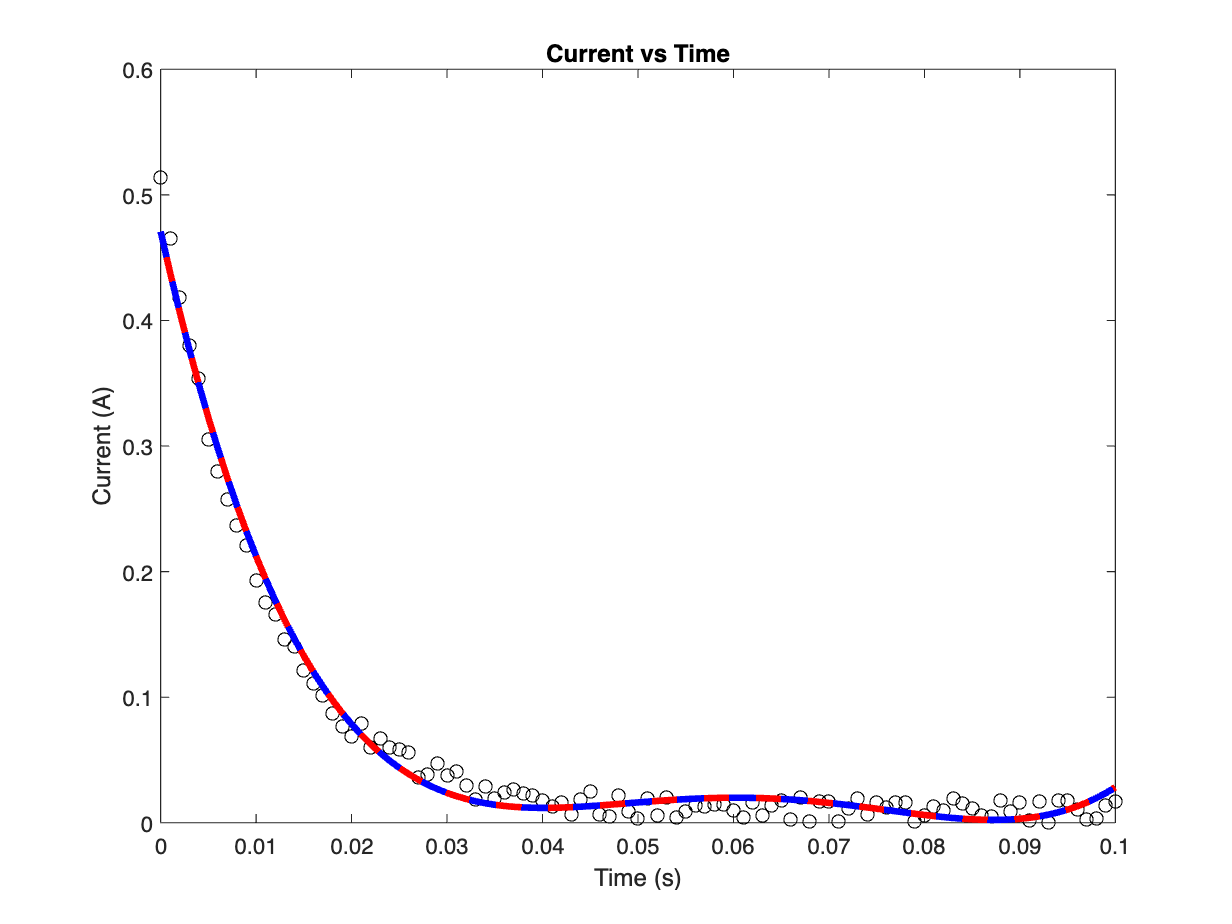

plot(tc,ic,'ko')
hold on
plot(tc,Ic,'r',"LineWidth",3)
plot(tc,Icmy,'b--',"LineWidth",3)
hold off
title("Current vs Time")
xlabel("Time (s)")
ylabel("Current (A)")

Using the algorithm you just developed from Fields 1 to 4, write a MATLAB function named $regre()$ with input variables $(x,y,m)$ where $x$ and $y$ are the data set and $m$ is the degree of the polynomial. Using your MATLAB function on the $normal$ data, solve for the regression coefficients and assign them to the variable $Bnmy$. Display the values of the coefficients.

% Field 5
% DO NOT CHANGE ANYTHING HERE
Bnmy = regre(tn,fn,m)

Bnmy = 1.0e+03 *

   -3.4848
    4.8701
   -2.4005
    0.4941
   -0.0362


Using the x-data set for normal, $tn$, generate the fitting curve for the normal data set from the coefficients obtained from the variable $Bnmy$ in Field 5. Assign these new data set to the variable $Fnmy$.

% Field 6
sumn = zeros(length(tn),1);
for i = 1:m+1
    sumn = sumn + Bnmy(i)*tn.^(i-1);
end
Fnmy = sumn;

Plot the best fit line, $(tn, Fn)$,  obtained from the MATLAB built-in function, the best fit line, $(tn,Fnmy)$ you just computed, and compare it in the same plot with the original normal data, $(tn, Fn)$. Use the same black circles for $(tn, Fn)$, a red solid line for $(tn, Fn)$, and a blue dashed line for $(tn, Fnmy)$, with LineWidths of 3 units, for the best fit lines. Add a title and the axes labels.

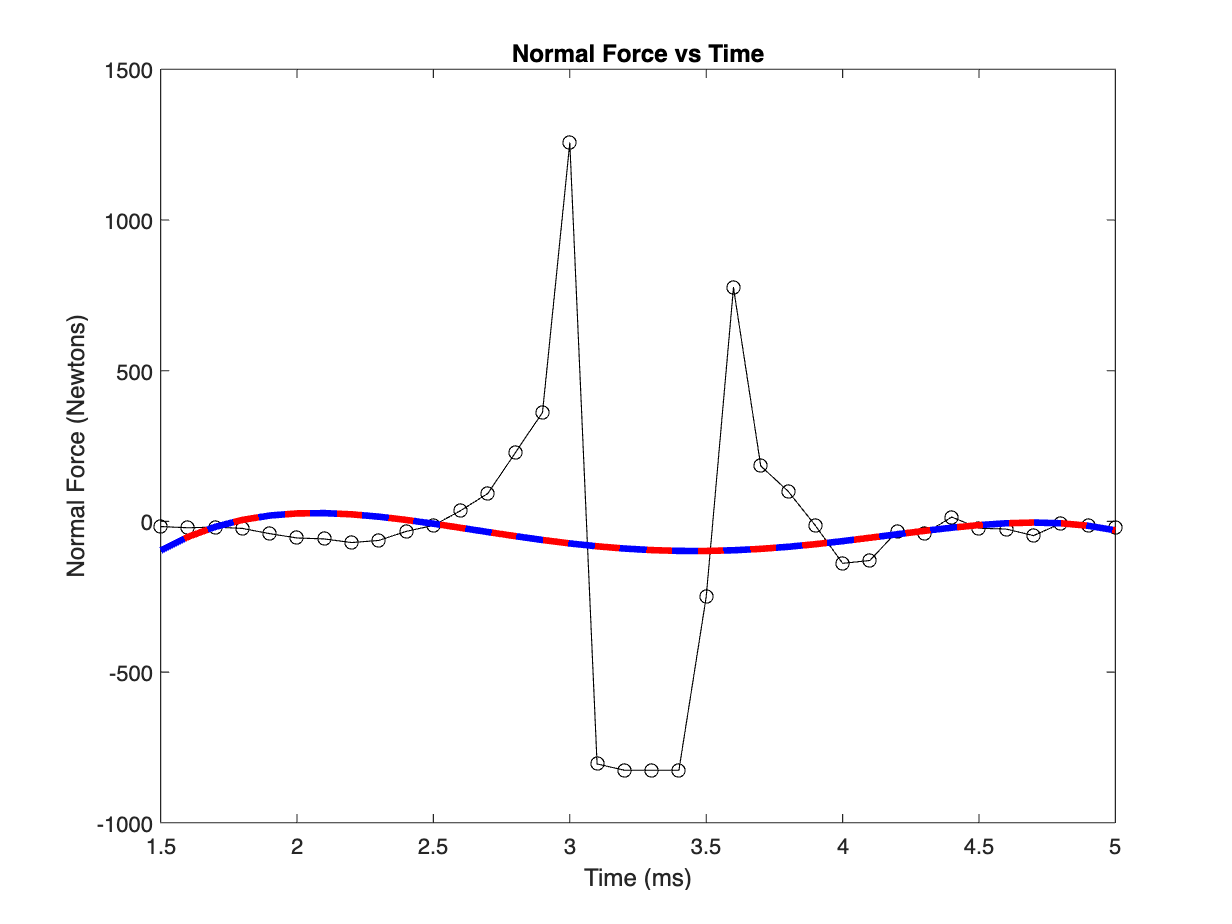

plot(tn,fn,'ko-')
hold on
plot(tn,Fn,'r',"LineWidth",3)
plot(tn,Fnmy,'b--',"LineWidth",3)
title("Normal Force vs Time")
ylabel("Normal Force (Newtons)")
xlabel("Time (ms)")
hold off

Solve for the error corresponding to $(tc,Icmy)$ and $(tn,Inmy)$. Assign the variables $ecmy$ and $enmy$ to the errors from the $current$ data set and the $normal$ data set, respectively. Compare these and $ec$ and $en$.

ec

ec = 0.0118

ecmy = sqrt(sum((Icmy-ic).^2)/(length(ic)-(m+1)))

ecmy = 0.0118

en

en = 406.3524

enmy = sqrt(sum((Fnmy-fn).^2)/(length(fn)-(m+1)))

enmy = 406.3524

Compare between MATLAB's built-in polyfit() function and your regre() function in terms of what you see in the graphs and the error values.

% Write your answer here


#### TASK 3. Set-up the cubic interpolation matrix

As in the previous task, using the same data sets, we are now going to develop an algorithm for spline interpolation and make our own spline function.

First, we need to define a new set of data points with respect to the x-axis variable that have more data points in between. We use the same variables, $tcq$ and $tnq$, as our query points. Using MATLAB's built-in $spline()$ function, generate the new values for the $current$ and $normal$ data and assign these new values to the variables, $Icspline$ and $Fnspline$. Add new 5 data points in between the existing data points.

q = 10;
tcq = linspace( min(tc),max(tc), length(tc) + (length(tc)-1)*q );
tnq = linspace( min(tn),max(tn), length(tn) + (length(tn)-1)*q );
Icspline = spline(tc,ic,tcq);
Fnspline = spline(tn,fn,tnq);

It's time to make our own spline interpolation function based on the video lecture. We are going to use cubic splines, and thus will be naming our function $cubint()$. As in the $spline()$ function, the first two arguments in the function are the x- and y-data sets, while the third argument is the query points. We begin by first studying this equation. 


$$\left(x_i -x_{i-1} \right)\textrm{f"}\left(x_{i-1} \right)+2\left(x_{i+1} -x_{i-1} \right)\textrm{f"}\left(x_i \right)+\left(x_{i+1} -x_i \right)\textrm{f"}\left(x_{i+1} \right)=\frac{6}{x_{i+1} -x_i }\left\lbrack f\left(x_{i+1} \right)-f\left(x_i \right)\right\rbrack +\frac{6}{x_i -x_{i-1} }\left\lbrack f\left(x_{i-1} \right)-f\left(x_i \right)\right\rbrack$$


The goal is to solve for the values of the second derivatives at the interior knots. If we have $n$ data points, then there are $n-2$ unknowns. So, we need to set up $n-2$ simultaneous equations. However, we will be setting up an $n\times n$ matrix first. What are the elements of this matrix. The first row elements are obtained from $i=2$. Using the above equation, we get


$$\left(x_2 -x_1 \right)\textrm{f"}\left(x_1 \right)+2\left(x_3 -x_1 \right)\textrm{f"}\left(x_2 \right)+\left(x_3 -x_2 \right)\textrm{f"}\left(x_3 \right)=\frac{6}{x_3 -x_2 }\left\lbrack f\left(x_3 \right)-f\left(x_2 \right)\right\rbrack +\frac{6}{x_2 -x_1 }\left\lbrack f\left(x_1 \right)-f\left(x_2 \right)\right\rbrack$$


The second row elements are obtained from $i=3$, which yields


$$\left(x_3 -x_2 \right)\textrm{f"}\left(x_2 \right)+2\left(x_4 -x_2 \right)\textrm{f"}\left(x_3 \right)+\left(x_4 -x_3 \right)\textrm{f"}\left(x_4 \right)=\frac{6}{x_4 -x_3 }\left\lbrack f\left(x_4 \right)-f\left(x_3 \right)\right\rbrack +\frac{6}{x_3 -x_2 }\left\lbrack f\left(x_2 \right)-f\left(x_3 \right)\right\rbrack$$


For $i=4$, we get


$$\left(x_4 -x_3 \right)\textrm{f"}\left(x_3 \right)+2\left(x_5 -x_3 \right)\textrm{f"}\left(x_4 \right)+\left(x_5 -x_4 \right)\textrm{f"}\left(x_4 \right)=\frac{6}{x_5 -x_4 }\left\lbrack f\left(x_5 \right)-f\left(x_4 \right)\right\rbrack +\frac{6}{x_4 -x_3 }\left\lbrack f\left(x_3 \right)-f\left(x_4 \right)\right\rbrack$$


This goes on until $i=n-1$, which we then obtain


$$\left(x_{n-1} -x_{n-2} \right)\textrm{f"}\left(x_{n-2} \right)+2\left(x_n -x_{n-2} \right)\textrm{f"}\left(x_{n-1} \right)+\left(x_n -x_{n-1} \right)\textrm{f"}\left(x_n \right)=\frac{6}{x_n -x_{n-1} }\left\lbrack f\left(x_n \right)-f\left(x_{n-1} \right)\right\rbrack +\frac{6}{x_{n-1} -x_{n-2} }\left\lbrack f\left(x_{n-2} \right)-f\left(x_{n-1} \right)\right\rbrack$$


We can rewrite these equations in matrix form to be


$$\begin{array}{l}
\left\lbrack \begin{array}{ccccccccc}
x_2 -x_1  & 2\left(x_3 -x_1 \right) & x_3 -x_2  & 0 & 0 & 0 & 0 & \cdots  & 0\\
0 & x_3 -x_2  & 2\left(x_4 -x_2 \right) & x_4 -x_3  & 0 & 0 & 0 & \cdots  & 0\\
0 & 0 & x_4 -x_3  & 2\left(x_5 -x_3 \right) & x_5 -x_4  & 0 & 0 & \cdots  & 0\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \ddots  & \\
0 & 0 & 0 & 0 & 0 & 0 & x_{n-1} -x_{n-2}  & 2\left(x_n -x_{n-2} \right) & x_n -x_{n-1} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\textrm{f"}\left(x_1 \right)\\
\textrm{f"}\left(x_2 \right)\\
\textrm{f"}\left(x_3 \right)\\
\vdots \\
\textrm{f"}\left(x_n \right)
\end{array}\right\rbrack =\\
\left\lbrack \begin{array}{c}
\frac{6}{x_3 -x_2 }\left\lbrack f\left(x_3 \right)-f\left(x_2 \right)\right\rbrack +\frac{6}{x_2 -x_1 }\left\lbrack f\left(x_1 \right)-f\left(x_2 \right)\right\rbrack \\
\frac{6}{x_4 -x_3 }\left\lbrack f\left(x_4 \right)-f\left(x_3 \right)\right\rbrack +\frac{6}{x_3 -x_2 }\left\lbrack f\left(x_2 \right)-f\left(x_3 \right)\right\rbrack \\
\frac{6}{x_5 -x_4 }\left\lbrack f\left(x_5 \right)-f\left(x_4 \right)\right\rbrack +\frac{6}{x_4 -x_3 }\left\lbrack f\left(x_3 \right)-f\left(x_4 \right)\right\rbrack \\
\vdots \\
\frac{6}{x_n -x_{n-1} }\left\lbrack f\left(x_n \right)-f\left(x_{n-1} \right)\right\rbrack +\frac{6}{x_{n-1} -x_{n-2} }\left\lbrack f\left(x_{n-2} \right)-f\left(x_{n-1} \right)\right\rbrack 
\end{array}\right\rbrack 
\end{array}$$


If we let 


$$A=\left\lbrack \begin{array}{ccccccccc}
x_2 -x_1  & 2\left(x_3 -x_1 \right) & x_3 -x_2  & 0 & 0 & 0 & 0 & \cdots  & 0\\
0 & x_3 -x_2  & 2\left(x_4 -x_2 \right) & x_4 -x_3  & 0 & 0 & 0 & \cdots  & 0\\
0 & 0 & x_4 -x_3  & 2\left(x_5 -x_3 \right) & x_5 -x_4  & 0 & 0 & \cdots  & 0\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \ddots  & \\
0 & 0 & 0 & 0 & 0 & 0 & x_{n-1} -x_{n-2}  & 2\left(x_n -x_{n-2} \right) & x_n -x_{n-1} 
\end{array}\right\rbrack$$


and 

$B=\left\lbrack \begin{array}{c}
\textrm{f"}\left(x_1 \right)\\
\textrm{f"}\left(x_2 \right)\\
\textrm{f"}\left(x_3 \right)\\
\vdots \\
\textrm{f"}\left(x_n \right)
\end{array}\right\rbrack$      and     $C=\left\lbrack \begin{array}{c}
\frac{6}{x_3 -x_2 }\left\lbrack f\left(x_3 \right)-f\left(x_2 \right)\right\rbrack +\frac{6}{x_2 -x_1 }\left\lbrack f\left(x_1 \right)-f\left(x_2 \right)\right\rbrack \\
\frac{6}{x_4 -x_3 }\left\lbrack f\left(x_4 \right)-f\left(x_3 \right)\right\rbrack +\frac{6}{x_3 -x_2 }\left\lbrack f\left(x_2 \right)-f\left(x_3 \right)\right\rbrack \\
\frac{6}{x_5 -x_4 }\left\lbrack f\left(x_5 \right)-f\left(x_4 \right)\right\rbrack +\frac{6}{x_4 -x_3 }\left\lbrack f\left(x_3 \right)-f\left(x_4 \right)\right\rbrack \\
\vdots \\
\frac{6}{x_n -x_{n-1} }\left\lbrack f\left(x_n \right)-f\left(x_{n-1} \right)\right\rbrack +\frac{6}{x_{n-1} -x_{n-2} }\left\lbrack f\left(x_{n-2} \right)-f\left(x_{n-1} \right)\right\rbrack 
\end{array}\right\rbrack$,

then in order to solve for $B$, we need to solve for

$B=A^{-1} C$.

Keep in mind that the boundary conditions dictate that $\textrm{f"}\left(x_1 \right)=\textrm{f"}\left(x_n \right)=0$.

In Field 7 below, set up matrices $A$ and $C$ simultaneously in one $for$ loop for the $current$ data set.

% Field 7
n = length(tc);
Adum = zeros((n-2),n);
C = zeros((n-2),1);
for i = 2:n-1
    %Matrix A
        Adum(i-1,i-1) = tc(i)-tc(i-1);
        Adum(i-1,i) = 2*(tc(i+1)-tc(i-1));
        Adum(i-1,i+1) = tc(i+1)-tc(i);
    %Matrix C
        e1 = (6/(tc(i+1)-tc(i)))*(ic(i+1)-ic(i));
        e2 = (6/(tc(i)-tc(i-1)))*(ic(i-1)-ic(i));
        C(i-1,1) = e1+e2;
end
A = Adum;
A(:,1) = [];
A(:,(n-1)) = []

A =     0.0040    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010    0.0040    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

A

A =     0.0040    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010    0.0040    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

C

C =    14.0002
   48.6719
   76.5861
 -140.9493
  145.7159
   12.9797
   11.7162
   31.4310
  -71.6243
   56.2678


In Field 8, solve for the matrix $B$ for the $current$ data set. 

% Field 8
Bdum = (inv(A))*C;
B(1,1) = 0;
B = [B;Bdum];
B(n,1) = 0;

B

B = 1.0e+04 *

         0
    0.2653
    0.3388
    3.2466
   -5.6666
    5.3247
   -1.0607
    0.2161
    1.3678
   -2.5441


The next step would be to solve for the best fit line using this equation


$$f_i \left(x\right)=\frac{\textrm{f"}\left(x_{i-1} \right)}{6\left(x_i -x_{i-1} \right)}{\left(x_i -x\right)}^3 +\frac{\textrm{f"}\left(x_i \right)}{6\left(x_i -x_{i-1} \right)}{\left(x-x_{i-1} \right)}^3 +\left\lbrack \frac{f\left(x_{i-1} \right)}{x_i -x_{i-1} }-\frac{\textrm{f"}\left(x_{i-1} \right)\left(x_i -x_{i-1} \right)}{6}\right\rbrack \left(x_i -x\right)+\left\lbrack \frac{f\left(x_i \right)}{x_i -x_{i-1} }-\frac{\textrm{f"}\left(x_i \right)\left(x_i -x_{i-1} \right)}{6}\right\rbrack \left(x-x_{i-1} \right)$$


where $x$ are your query points. We start with $i=2$ and work our way up to $i=n$. To solve for $f_i \left(x\right)$, the query points must be $x_{i-1} \le x<x_i$. 

In Field 9, solve for the best fit line for the $current$ data assigning it to the variable, $Icmyspline$.

% Field 9
Icmyspline = zeros(size(tcq,1),size(tcq,2));
k = 1;
for i = 2:length(tc)
    while ( tcq(k) < tc(i) )
        den = tc(i)-tc(i-1);
        term1 = ( B(i-1)/(6*den) )*( tc(i) - tcq(k) )^3;
        term2 = ( B(i)/(6*den) )*( tcq(k) - tc(i-1) )^3;
        term3 = ( ic(i-1)/den - B(i-1)*den/6 )*( tc(i) - tcq(k) );
        term4 = ( ic(i)/den - B(i)*den/6 )*( tcq(k) - tc(i-1) );
        Icmyspline(k) = term1 + term2 + term3 + term4;
        k = k + 1;
    end
end

Plot the best fit line, $(tcq, Icspline)$ obtained from the MATLAB built-in function, the best fit line, $(tcq,Icmyspline)$ you just computed, and compare it in the same plot with the original current data, $(tc, ic)$. Use the same black circles for the $current$ data and a red line, with a LineWidth of 3 units, for the best fit line. Use the same black circles for $(tc, ic)$, a red solid line for $(tcq, Icspline)$, and a blue dashed line for $(tcq, Icmyspline)$, with LineWidths of 3 units, for the best fit lines. Add a title and the axes labels.

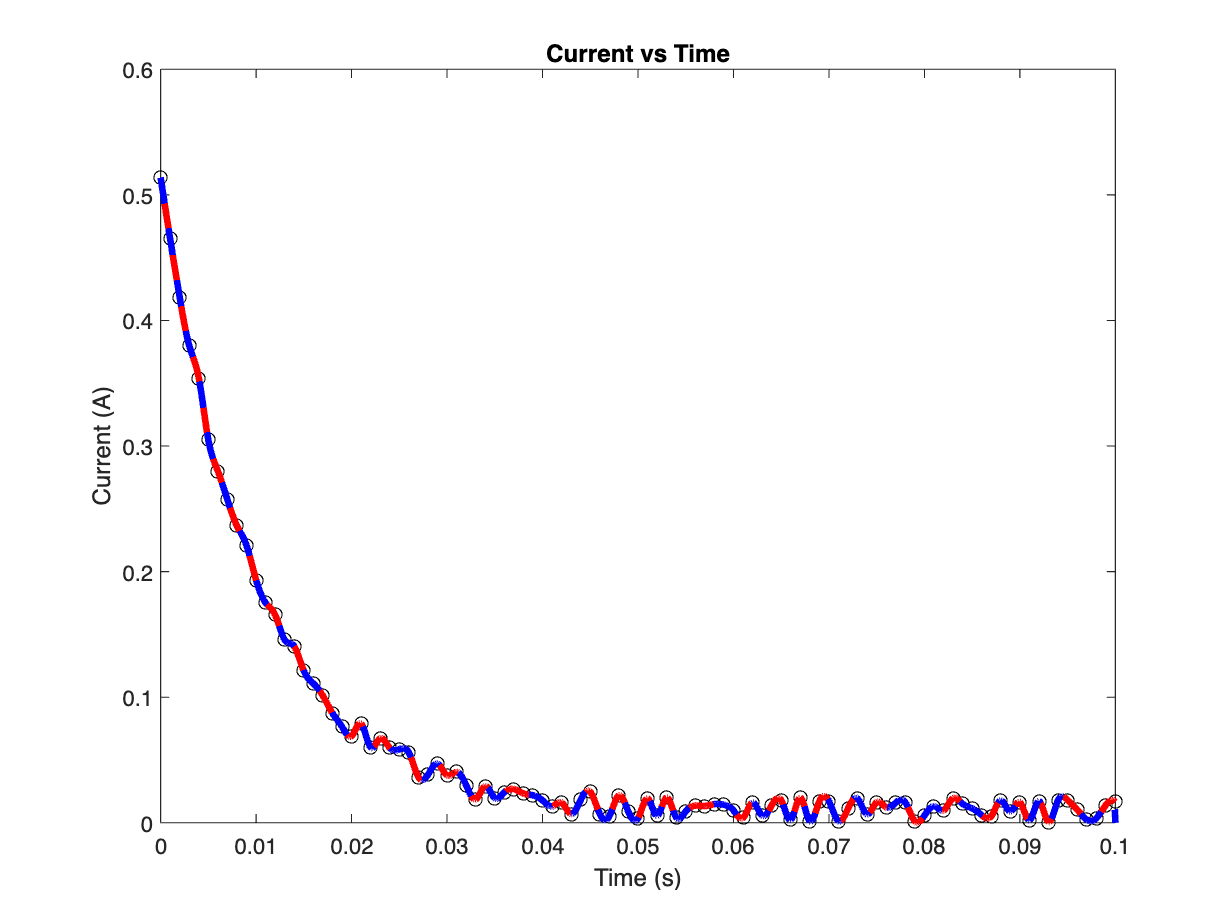

plot(tc,ic,'ko')
hold on
plot(tcq,Icspline,'r',"LineWidth",3)
plot(tcq,Icmyspline,'b--',"LineWidth",3)
hold off
title("Current vs Time")
xlabel("Time (s)")
ylabel("Current (A)")

Using the algorithm you just developed from Fields 7 to 9, write a MATLAB function named $cubint()$ with input variables $(x,y,qx)$ where $x$ and $y$ are the data set and $qx$ is set of querypoints. The output of the function is the best fit line $qy$. When you're finished, run this section to see if your program works. Use your MATLAB function to generate the new interpolating function, $Fnmyspline$, for the $normal$ data set.

% Field 10
Fnmyspline = cubint(tn,fn,tnq);

Plot the best fit line, $(tnq, Fnspline)$ obtained from the MATLAB built-in function, the best fit line, $(tnq,Fnmyspline)$ you just computed,  and compare it in the same plot with the original $normal$ data set, $(tn, fn)$. Use the same black circles and solid lines for the $normal$ data set and a red line, with a LineWidth of 3 units, for the best fit line. 

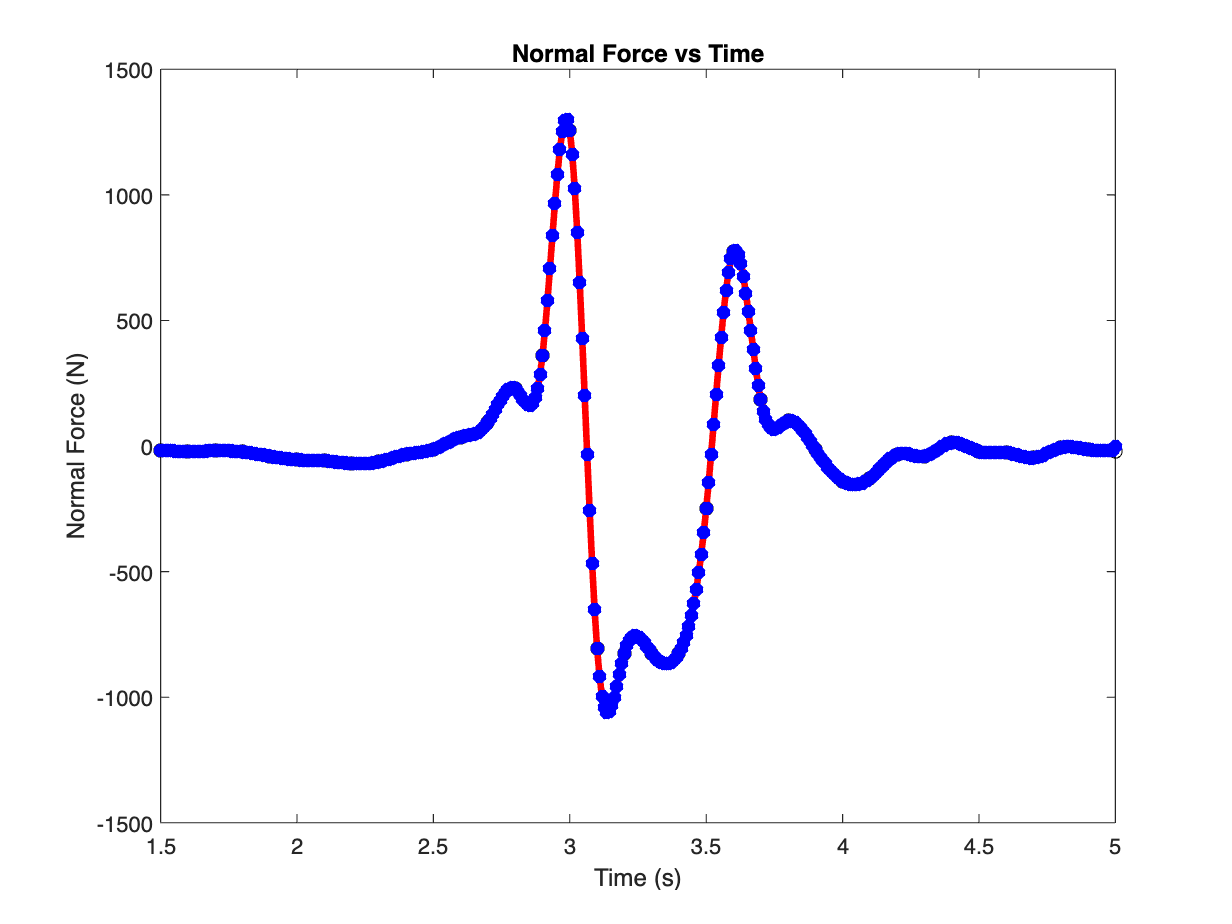

plot(tn,fn,'ko')
hold on
plot(tnq, Fnspline,'r',"LineWidth",3)
plot(tnq, Fnmyspline,'b*',"LineWidth",3)
hold off
title("Normal Force vs Time")
xlabel("Time (s)")
ylabel("Normal Force (N)")

Compare qualitatively between MATLAB's built-in $polyfit()$ function and your $regre()$ function in terms of what you see in the graph.

% Write your answer here
